# MATLAB Visualizations

## `plot`

- Most common plotting tool in MATLAB

- Basic syntax involves only two arrays of numbers *X *and *Y*

-  *h *can be used to refer to the plot in later code

- `LineSpec` specifies line, marker type, and colors

- `Name,Value `pairs are another way to specify line and marker properties

X = sort(rand(12,1));
Y = sort(rand(12,1));
h=plot(X,Y)

h =   Line with properties:

              Color: [0 0.447 0.741]
          LineStyle: '-'
          LineWidth: 0.5
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.119 0.16261 0.22381 0.27603 0.34039 0.49836 0.58527 0.6551 0.6797 0.70936 0.75469 0.95974]
              YData: [0.13862 0.14929 0.25428 0.2551 0.25751 0.50596 0.54722 0.69908 0.75127 0.84072 0.8909 0.95929]

  Show all properties


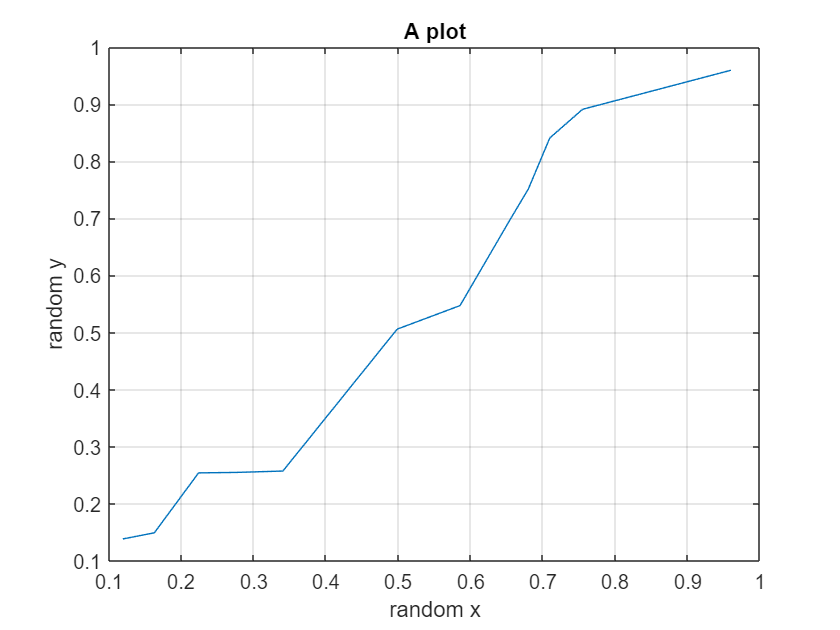

grid on
xlabel('random x')
ylabel(['random y'])
title("A plot")

Y = h.XData

Y =         0.119      0.16261      0.22381      0.27603      0.34039      0.49836      0.58527       0.6551       0.6797      0.70936      0.75469      0.95974


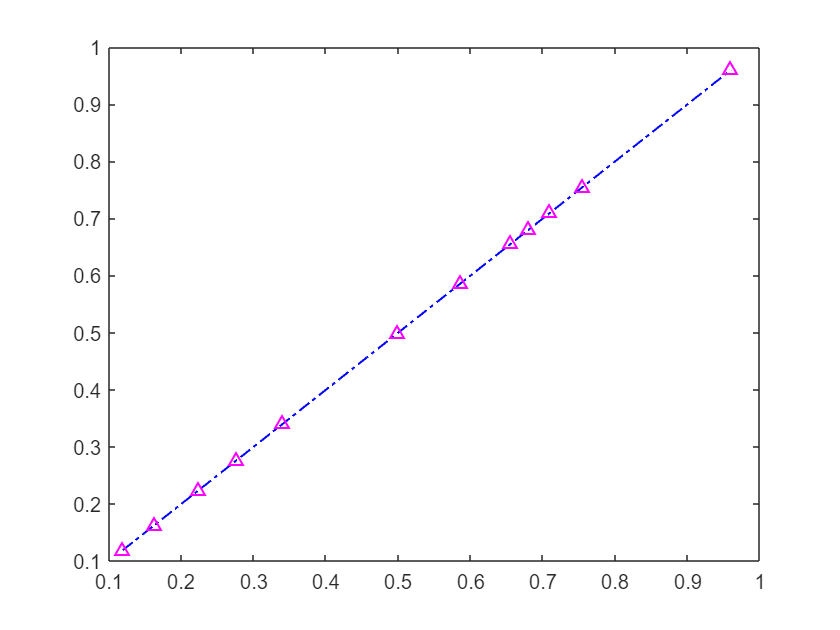

h =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-.'
          LineWidth: 1
             Marker: '^'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.119 0.16261 0.22381 0.27603 0.34039 0.49836 0.58527 0.6551 0.6797 0.70936 0.75469 0.95974]
              YData: [0.119 0.16261 0.22381 0.27603 0.34039 0.49836 0.58527 0.6551 0.6797 0.70936 0.75469 0.95974]

  Show all properties


h.YData=Y

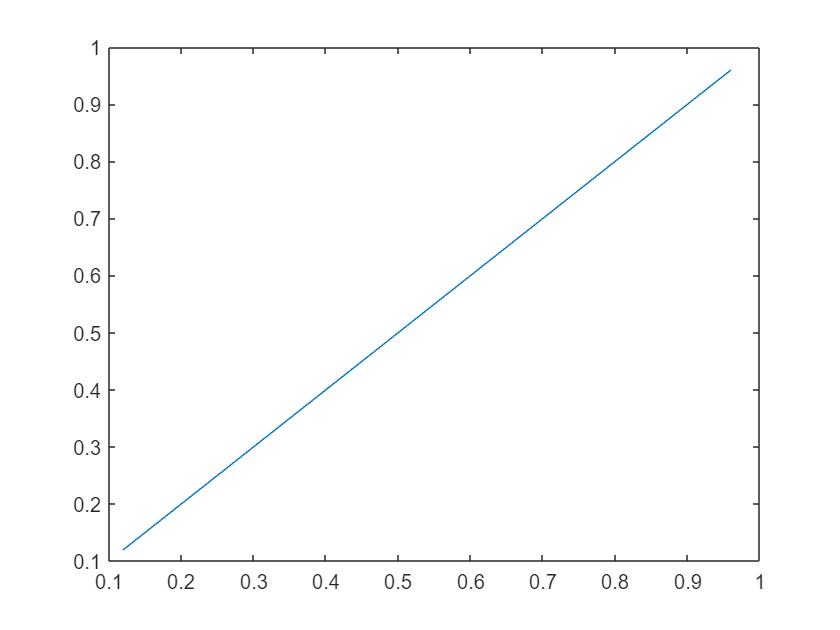

plot(X,Y)

MATLAB specifiers include

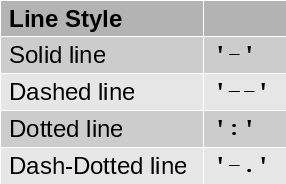

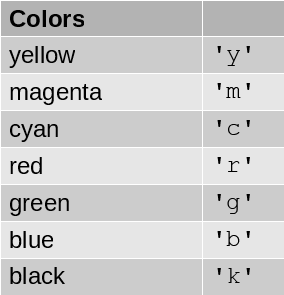

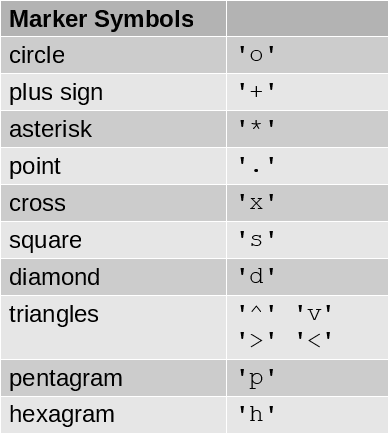

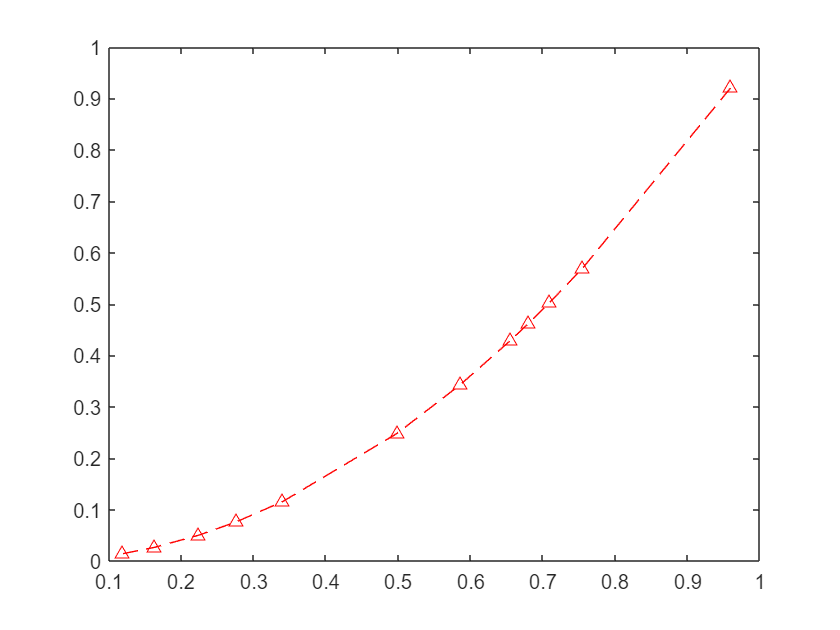

plot(X,X.^2,['^r--'])

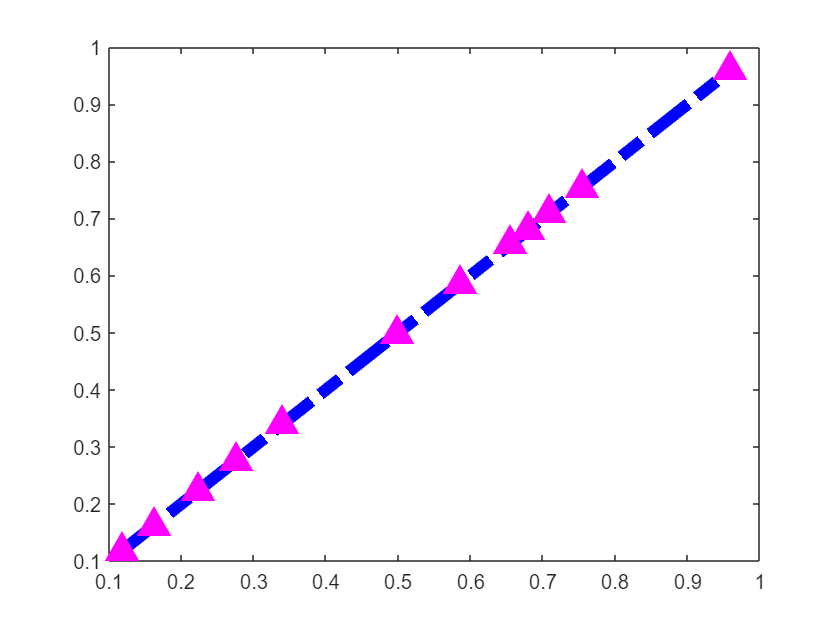

h =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-.'
          LineWidth: 6
             Marker: '^'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.119 0.16261 0.22381 0.27603 0.34039 0.49836 0.58527 0.6551 0.6797 0.70936 0.75469 0.95974]
              YData: [0.119 0.16261 0.22381 0.27603 0.34039 0.49836 0.58527 0.6551 0.6797 0.70936 0.75469 0.95974]

  Show all properties


h = plot(X,Y,['b-.^'] ,'LineWidth', 6, 'MarkerEdgeColor','m')

## Related Functions to `plot`

There are commands to include titles, axes labels, and other modifications.

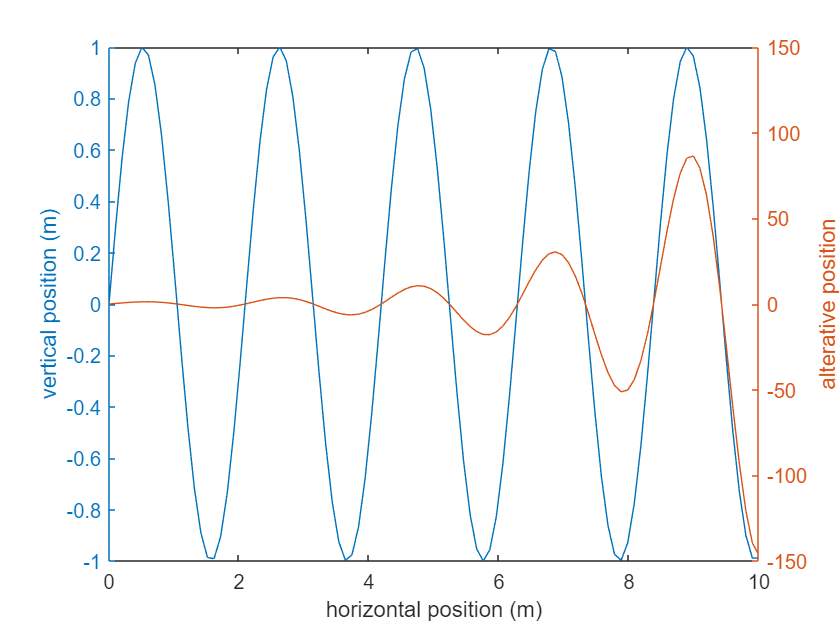

clf % clears the current figure
x = linspace(0,10); % linspace creates an array in the range of 0 to 10
y = sin(3*x);
yyaxis left; % sets next plot statement to use left side y axis
plot(x,y);
xlabel('horizontal position (m)');
ylabel('vertical position (m)');

z = sin(3*x).*exp(0.5*x);
yyaxis right; % sets next plot statement to use right y axis
plot(x,z)
ylabel('alterative position');
ylim([-150 150])

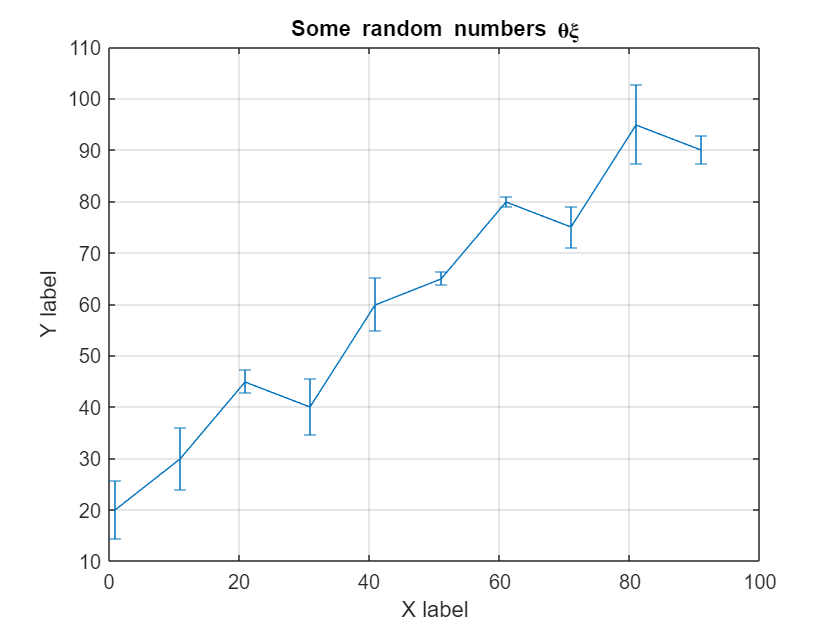

clf % clears current figure window
x = 1:10:100;
y = [20 30 45 40 60 65 80 75 95 90];
err = 8*rand(size(y));
errorbar(x,y,err) % plots with errorbars

title(['Some random numbers \theta\xi'])
xlabel('X label')
ylabel('Y label')
grid on

## Scatterplots

MATLAB produces scatterplots using the function` scatter`. `scatter `syntax looks like

`scatter``(X,Y)`

`scatter(``X,Y``,sz``)`

`scatter(``X,Y``,sz,``c``)`

`scatter(___,'filled')`

`scatter``(___,’<``markertype``>')`

`scatter(___,'``Name','Value``')`

`scatter(ax,___)`

`scatter3(___)`

- creates a 2-D scatter plot

- defines the area of the points (scalar or vector)

- defines the color of the plot (scalar or vector)

- `'filled' `specifies whether markers are filled

- `'markertype``'`, `'Name'`, and `'Value'`follows the same conventions as the function plot

- `scatter3 `creates a 3-D scatter plot  

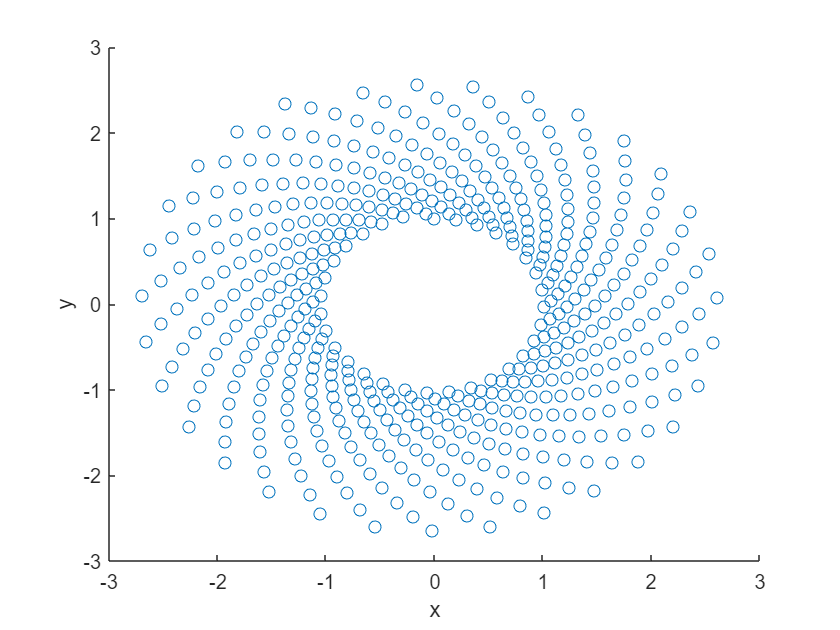

theta = linspace(0,1,500); % 500 points between 0 and 1
x = exp(theta).*sin(100*theta);
y = exp(theta).*cos(100*theta);
s = scatter(x,y);
xlabel('x');
ylabel('y');

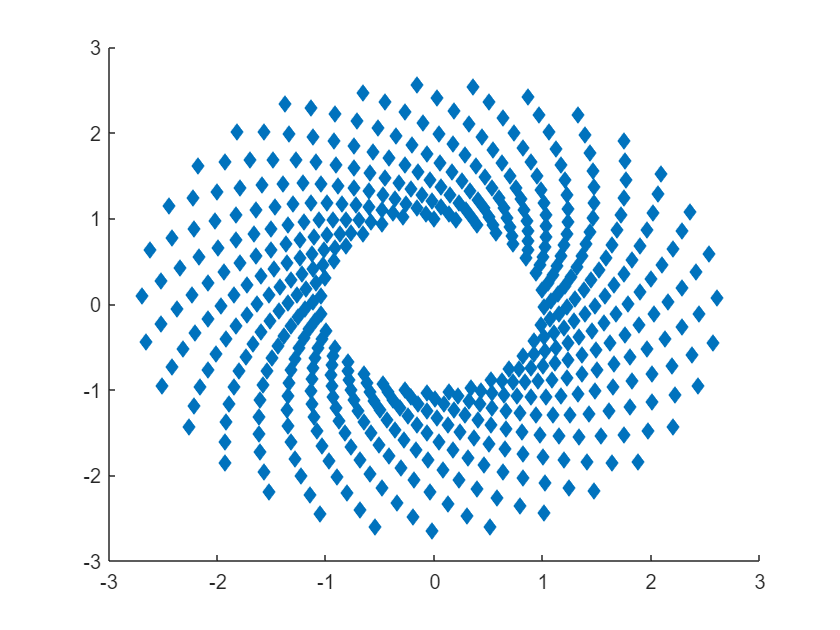

scatter(x,y,'filled','d'); % defines filled diamonds

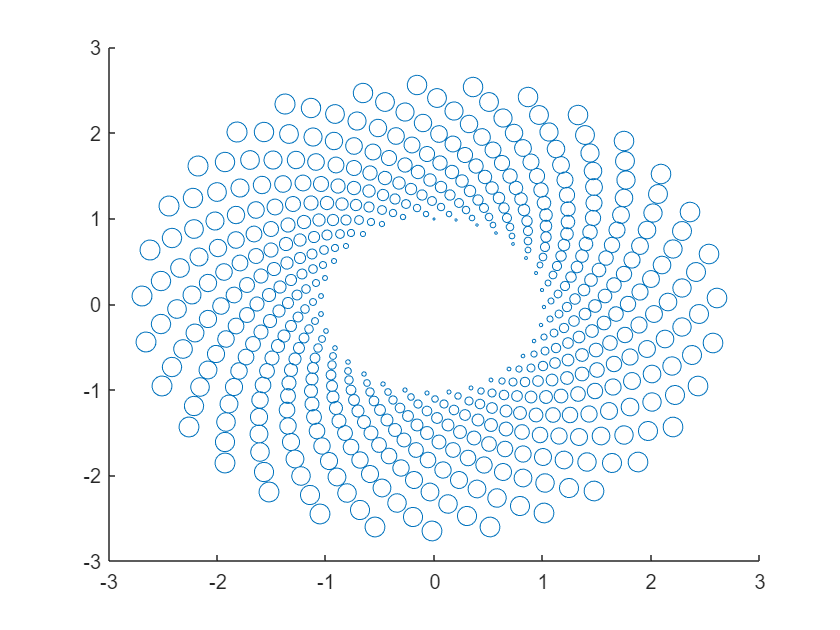

sz = linspace(1,100,500); % array to change the size of every point
scatter(x,y,sz)

X =55

X =     55


Y =-10

Y =    -10


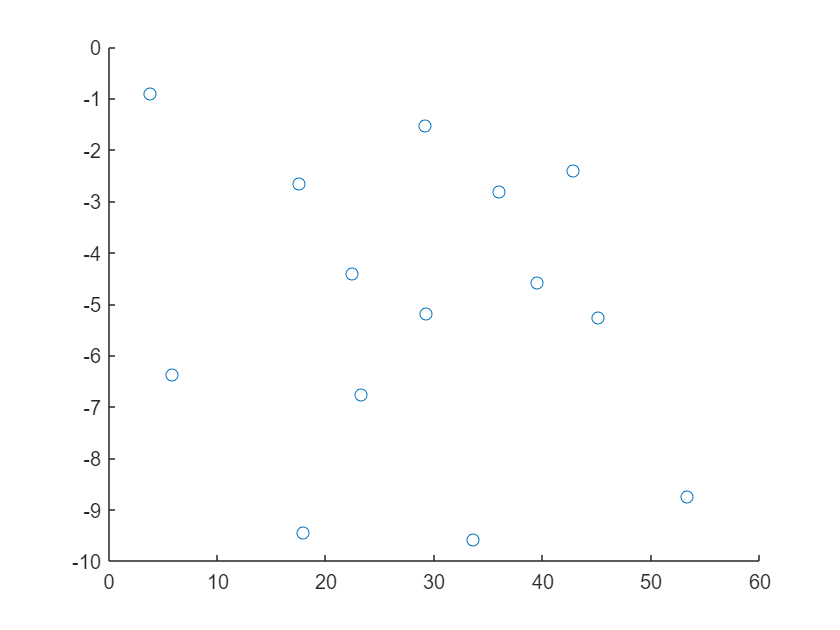

scatter(rand(14,1)*X, rand(14,1)*Y)

## Contour Plots

MATLAB produces contour plots using `contour`:

`contour(Z)`

`contour(``Z,n``)`

`contour(X,Y,Z)`

`contour(``X,Y,Z,n``)`

`contour(___,'``LineSpec``')`

`contour(___,'``Name','Value``')`

`contour(ax,___)`

`[``C,h``] = contour(___)`

`[``C,h``] = contour3(___)`

- creates a contour plot of the matrix *Z, *where columns correspond to *x*-coordinates and rows to *y*-coordinates

- *n *specifies number of contour lines (isolines)

- *X *and *Y (*same size as *Z) *determine the x- and y-coordinates in the plot

- *C *contains the contour matrix

- *h *contains the plot object (refer to this to change properties of the contour plot)

Z = rand(5,5) % random matrix of values

Z =     0.8256    0.1117    0.4950    0.9296    0.9889
    0.7900    0.1363    0.1476    0.6967    0.0005
    0.3185    0.6787    0.0550    0.5828    0.8654
    0.5341    0.4952    0.8507    0.8154    0.6126
    0.0900    0.1897    0.5606    0.8790    0.9900


contour(Z) % contour plot the random values above

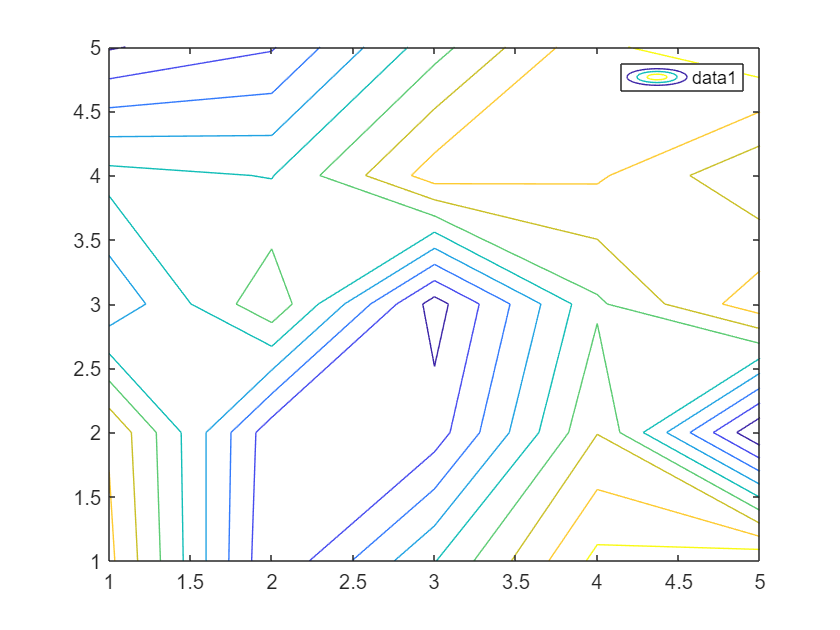

legend('show')

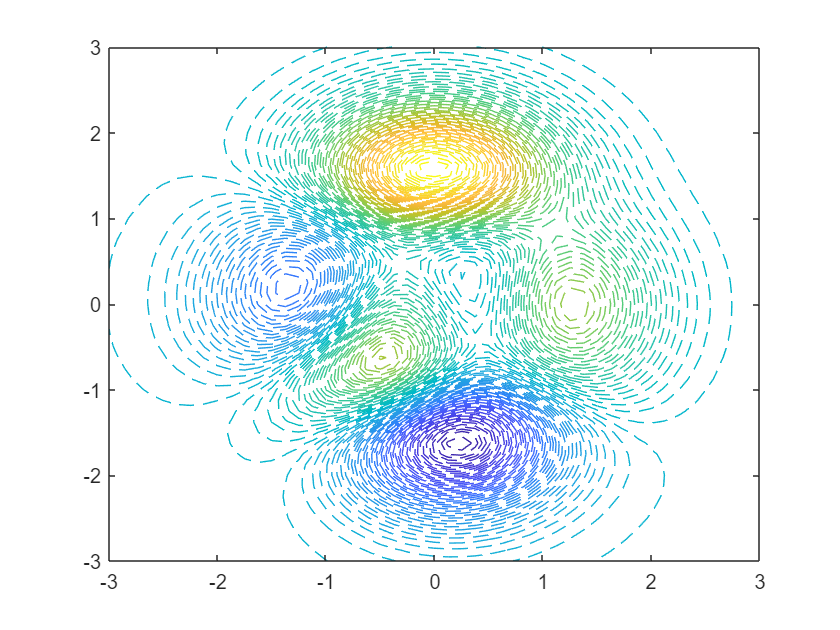

[X,Y,Z]=peaks; %peaks is a built-in functions that produces the plot below. type peaks into the command line and see what happens
contour(X,Y,Z,100,'--')

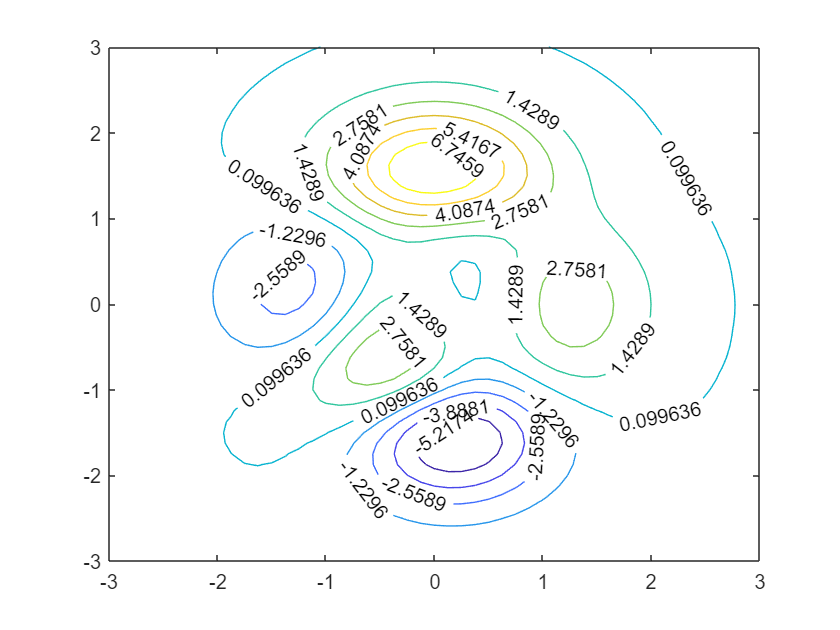

contour(X,Y,Z,10,'Showtext','on')

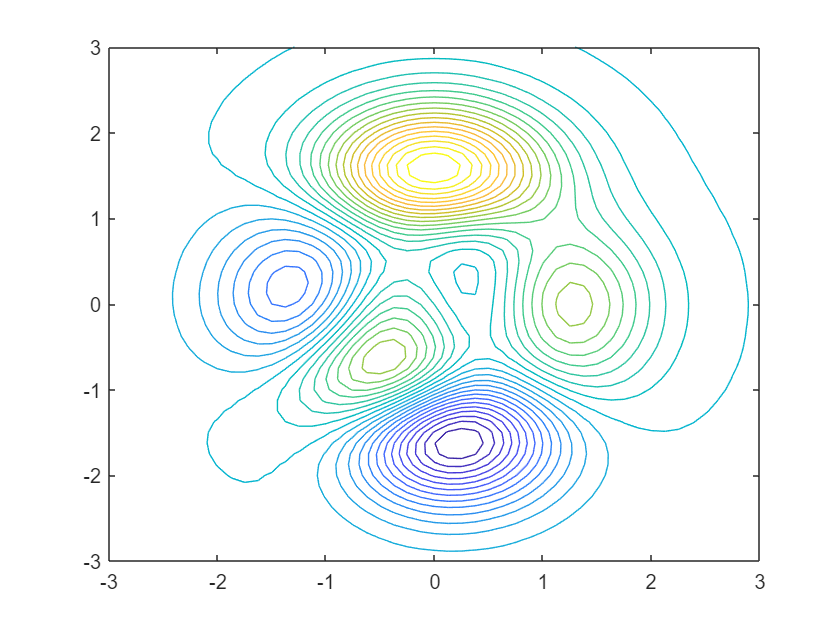

contour(X,Y,Z,30,'Showtext','off')

## Histograms

`histogram(X)`

`histogram(``X,nbins``)`

`histogram(``X,edges``)`

`histogram(___,'``Name','Value``')`

`histogram``(ax,___)`

`h = histogram(___)`

- creates histogram of the vector *X*

- specify number of bins (`nbins`) or the edges of the bins (`edges`)

- `'Name'` / `'Value' `pairs allow you to change the bin width, color, outline color, etc.

- histogram returns an object `h` for future modification reference

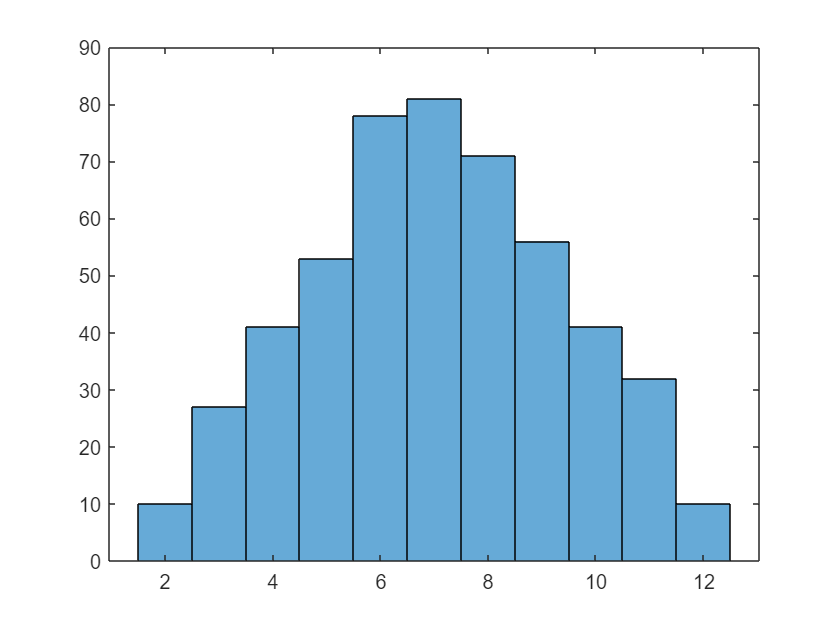

% Role of the dice
x = randi([1,6],500,1); % returns 500 random numbers between 1 and 6
y = randi([1,6],500,1);
histogram(x+y);

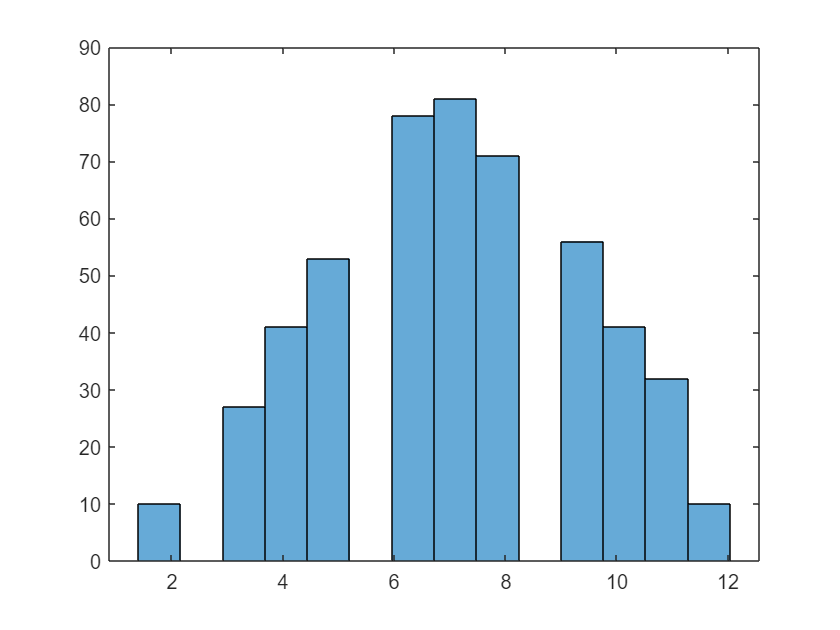

histogram(x+y,14); % changes number of bins

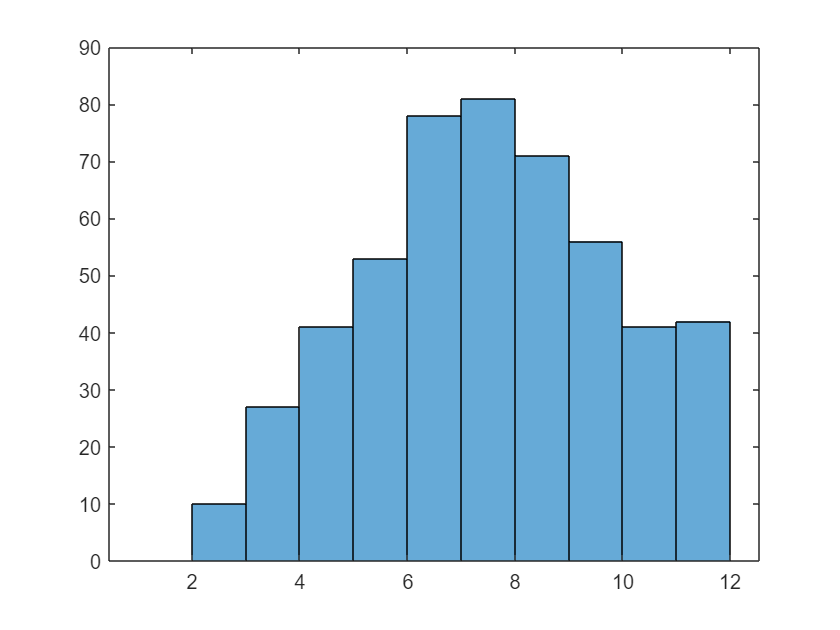

h1 =   Histogram with properties:

             Data: [500×1 double]
           Values: [0 10 27 41 53 78 81 71 56 41 42]
          NumBins: 11
         BinEdges: [1 2 3 4 5 6 7 8 9 10 11 12]
         BinWidth: 1
        BinLimits: [1 12]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


edges = [1:12];
h1=histogram(x+y,edges)

You can even make categorical histograms

A = [0 0 1 1 1 0 0 0 0 NaN NaN 1 0 0 0 1 0 1 0 1 0 0 0 1 1 1 1];
C = categorical(A,[1 0 NaN],{'yes','no','undecided'})

C = 1×27 categorical array
     no      no      yes      yes      yes      no      no      no      no      undecided      undecided      yes      no      no      no      yes      no      yes      no      yes      no      no      no      yes      yes      yes      yes 


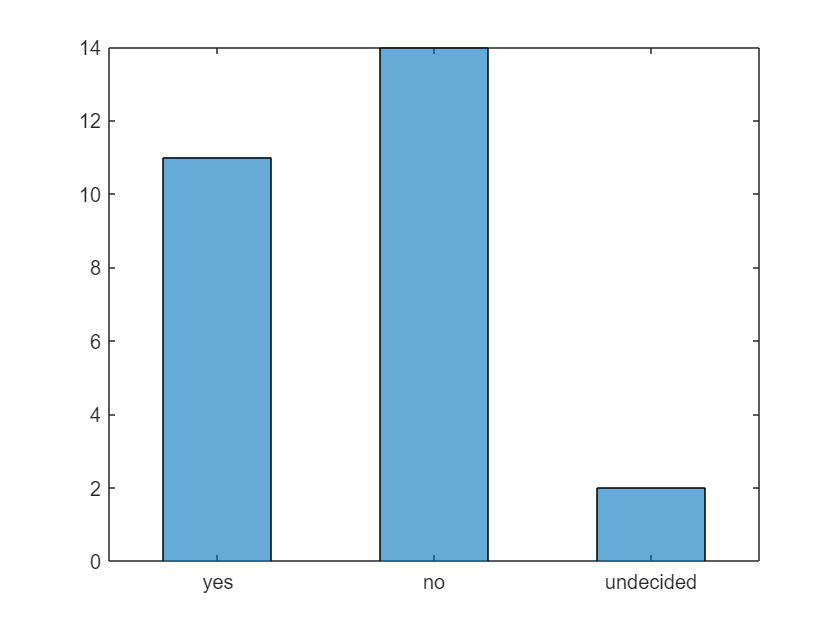

h = histogram(C,'BarWidth',0.5);

## Displaying Vectors

You have a variety of options when displaying vectors in MATLAB. 

**quiver **- 

- creates a vector field

- plots a vector <u,v> at every point <x,y>

- scale the vectors to any size

- specify display options using `Linespec` or `Name|Value` pairs

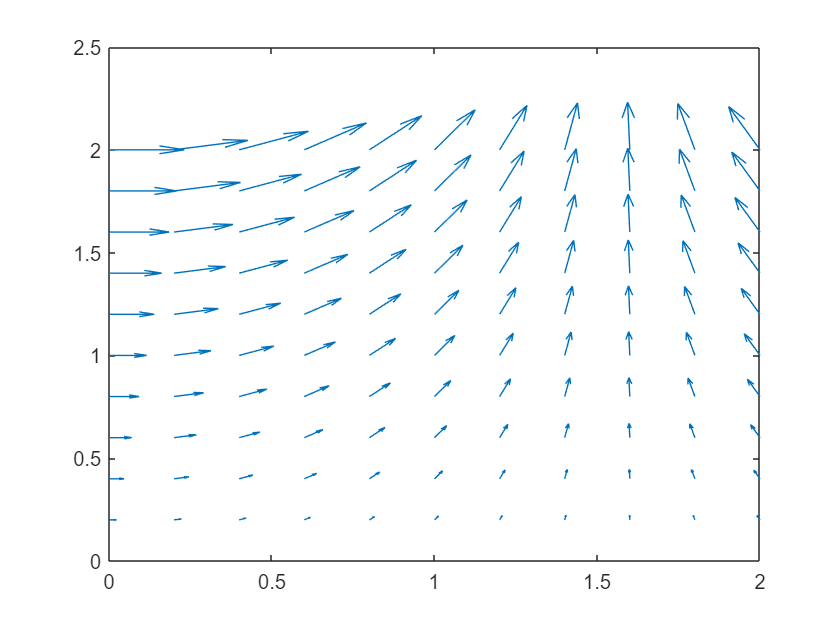

[x,y] = meshgrid(0:0.2:2,0:0.2:2); % What does meshgrid do?
u = cos(x).*y;
v = sin(x).*y;

quiver(x,y,u,v)

**feather**

- creates vectors emanating from equally spaced points along a horizontal axis

- express the vector components U and V relative to the origin of the respective vector

- Z is a complex number, using it is equivalent to `feather(real(Z),imag(Z)) `

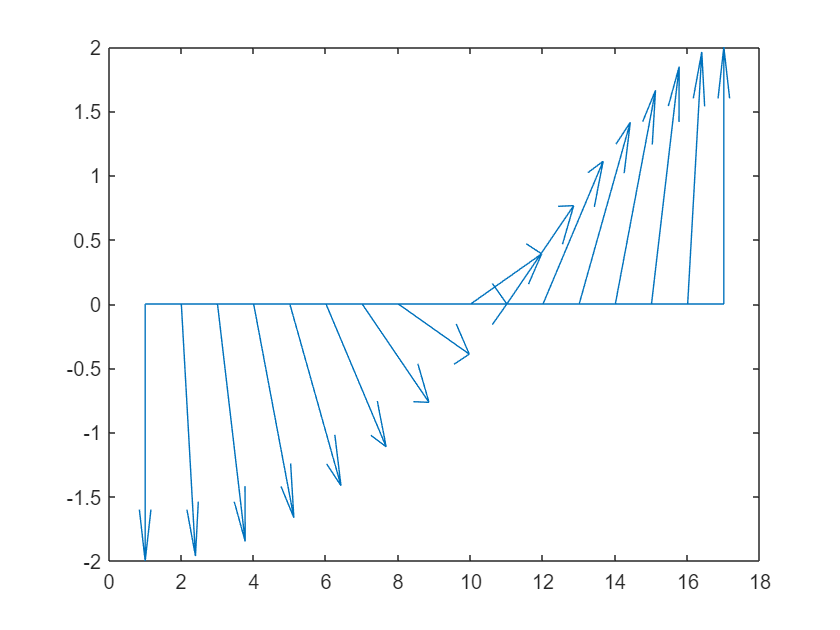

theta = -pi/2:pi/16:pi/2;
r = 2*ones(size(theta));
[u,v] = pol2cart(theta,r);
feather(u,v)

**compass**

operates just as feather but the vectors originate at the origin of a compass plot

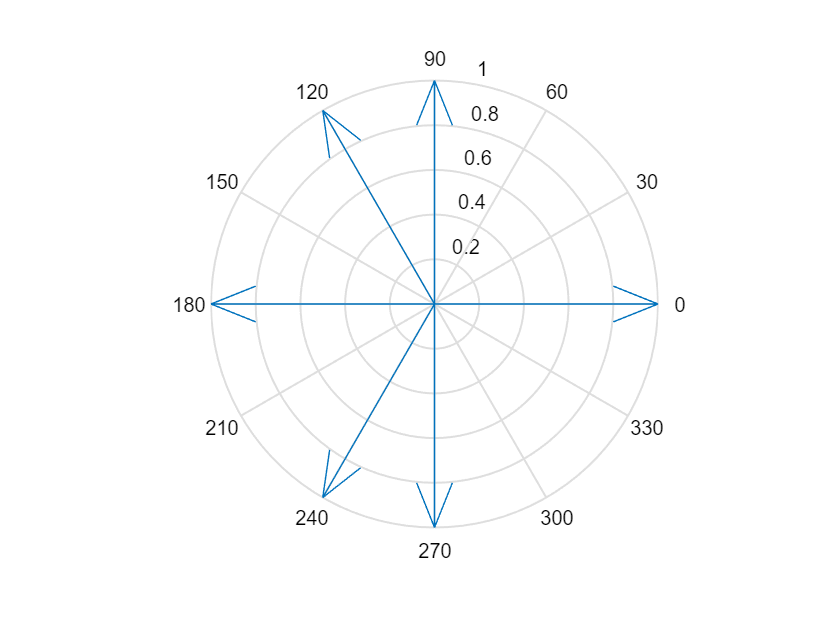

n = -4:4;
Z = exp(2*pi*i./n);
compass(Z)

## Animated Plots

- To see lines drawn by MATLAB, use the function `animatedline`

- it has the same syntax as plot

- Use `addpoints` to add points as the program process

- `pause(n)`halts the program execution for n seconds if you desire a slower animation.

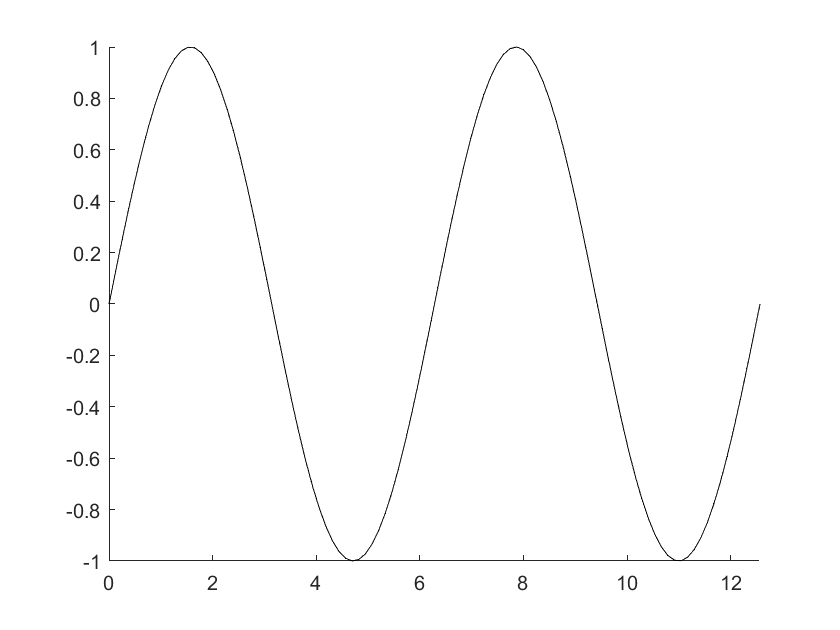

clf
h = animatedline;
axis([0,4*pi,-1,1])
x = linspace(0,4*pi,100);
y = sin(x);
for k = 1:length(x)
    addpoints(h,x(k),y(k));
    drawnow
end

Check out comet!!! It has less overhead.

## Movies

You can use the method `getframe `to construct movies illustrating motion. For example, to illustrate a standing wave of harmonic number `n` you can using a sinusodial function to modify the wave pattern capture the frames in a for loop:

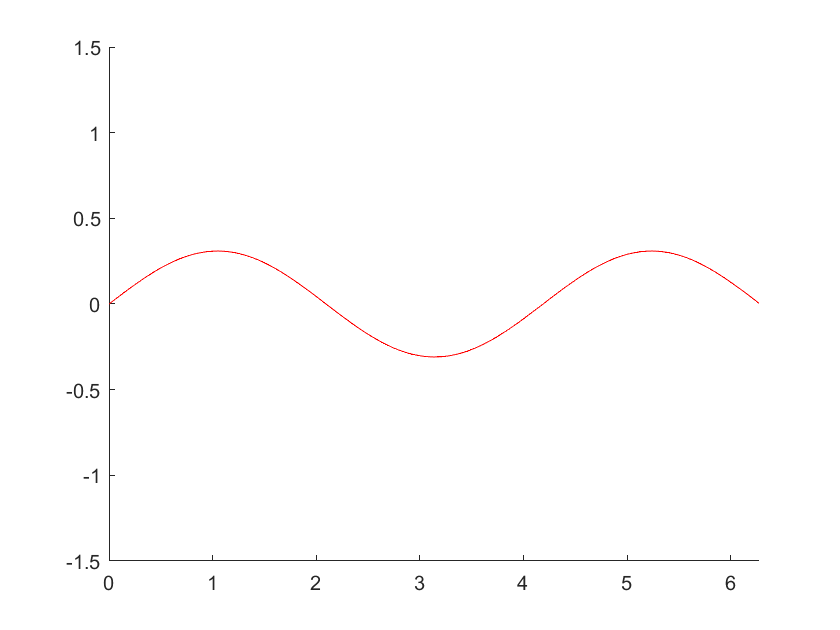

h=figure;
nodes = 1.5;
x = 0:0.01:6.28;
axis([0 2*pi -1.5 1.5])
ax = gca;
ax.NextPlot = 'replaceChildren';
loops =80;
M1(loops) = struct('cdata',[],'colormap',[]);
h.Visible = 'off';
for k = 1:loops
    fact = sin(k*pi/10);
    plot(x,fact*sin(nodes*x),'r')
    drawnow
    M1(k) = getframe;
end

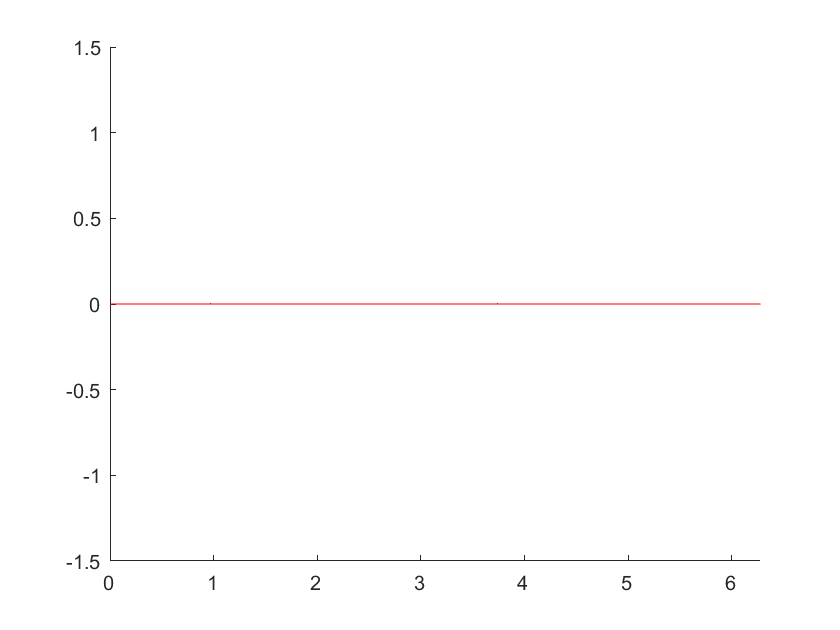

h.Visible = 'on';
movie(M1)

In another example buried in the MathWorks documentation files, they oscillate the built-in function `peaks`.

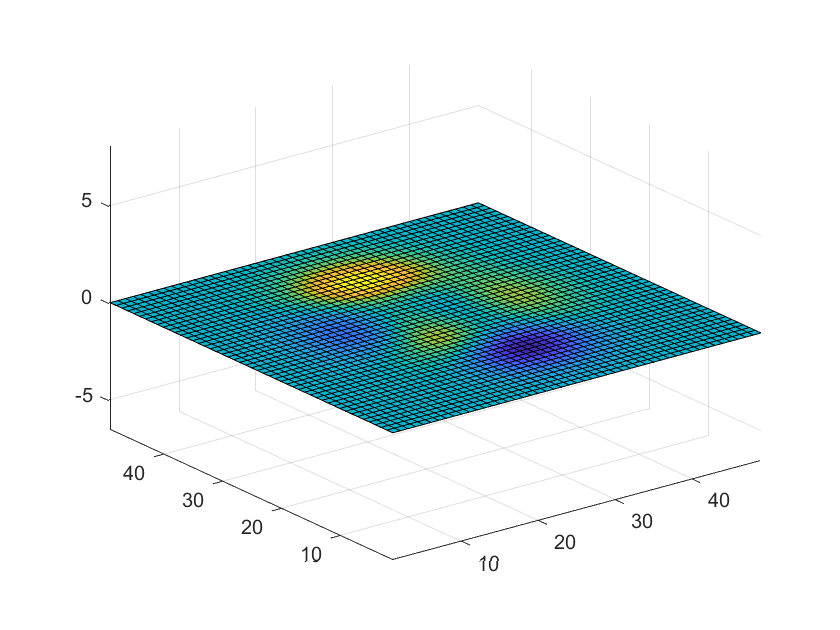

h = figure;
Z = peaks;
surf(Z)
axis tight manual
ax = gca;
ax.NextPlot = 'replaceChildren';
loops = 80;
M2(loops) = struct('cdata',[],'colormap',[]);
h.Visible = 'off';
for j = 1:loops
    X = sin(j*pi/10)*Z;
    surf(X,Z)
    drawnow
    M2(j) = getframe;
end
h.Visible = 'on';
movie(M2);